% Parámetros del sistema
m = 0.027; % Masa de la pelota (kg)
g = -9.81; % Gravedad (m/s^2)
r = 0.02742; % Distancia del servo al brazo (m)
L = 0.30; % Longitud del brazo (m)
R = 0.02; % Radio de la pelota (m)
I = (2/5) * m * R^2 % Momento de inercia de la pelota

I = 4.3200e-06


s=tf('s');
% Constante de la función de transferencia
G = (-m * g * R) / (L * s*s * (m + I / (R * R)))


G =
 
   0.005297
  -----------
  0.01134 s^2
 
Continuous-time transfer function.
Model Properties


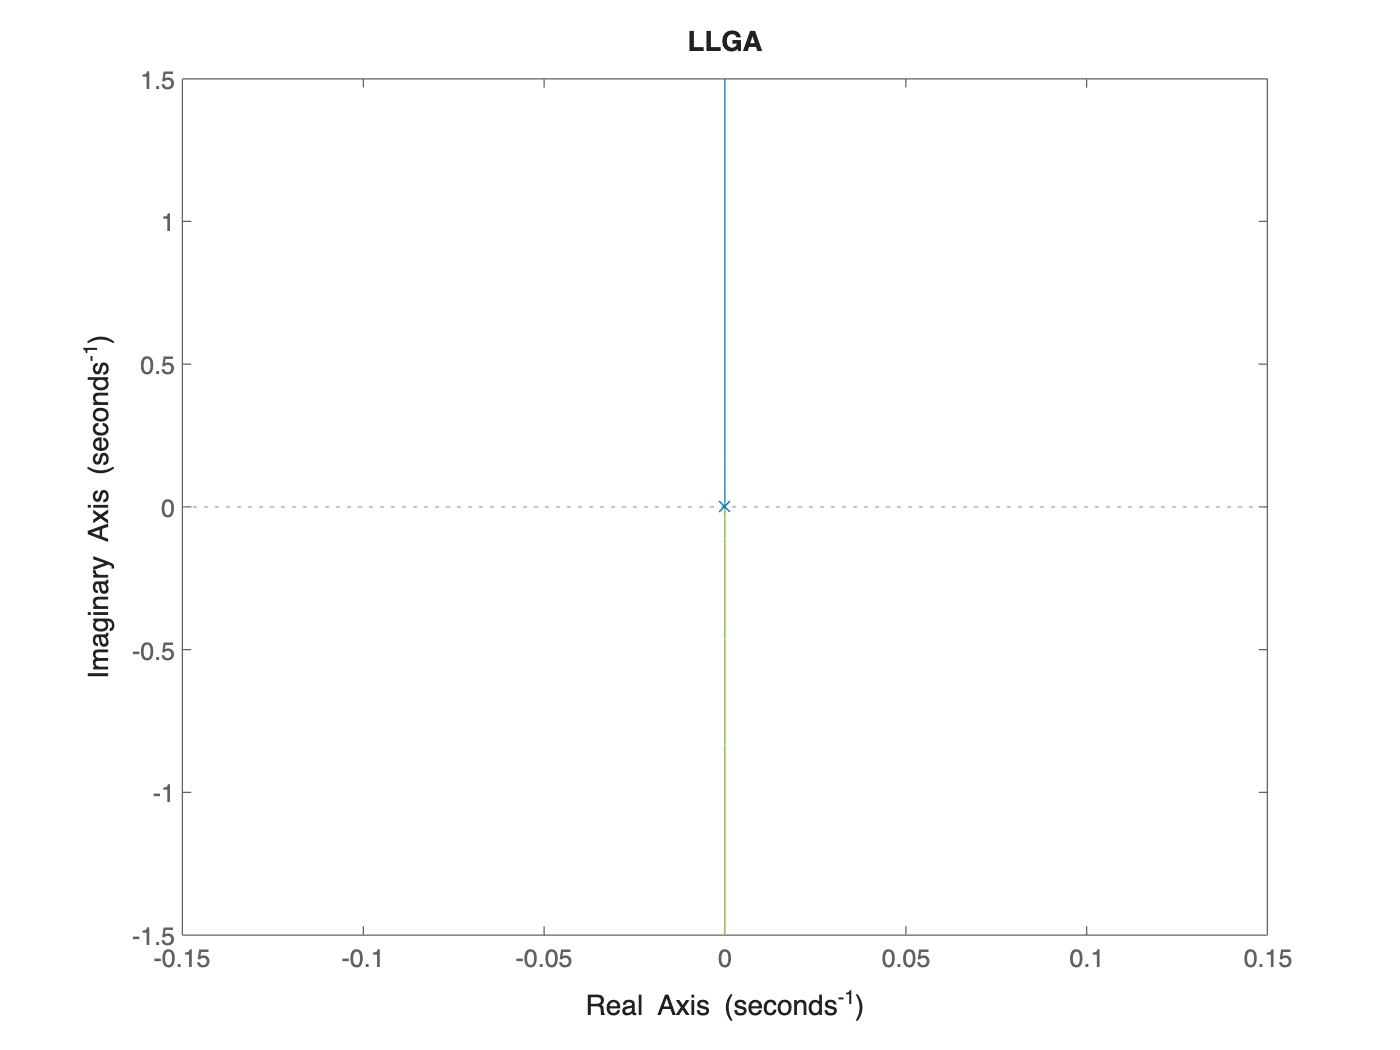

%figure;
rlocus(G);
title('LLGA');

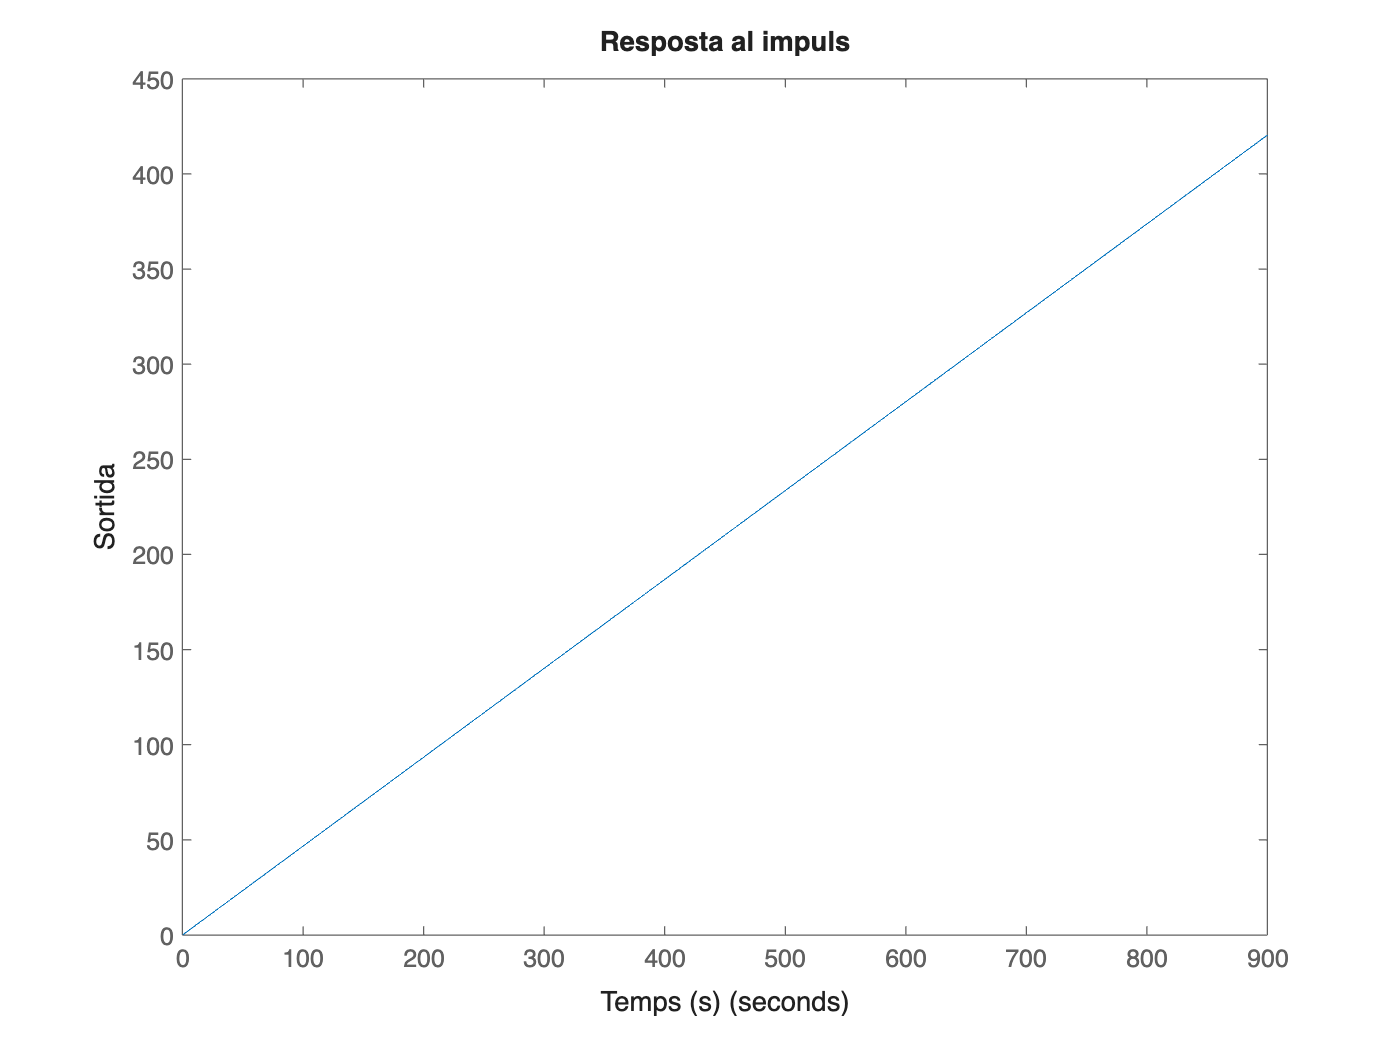

% 2. Respuesta al impulso
figure;
impulse(G);
title('Resposta al impuls');
xlabel('Temps (s)');
ylabel('Sortida');

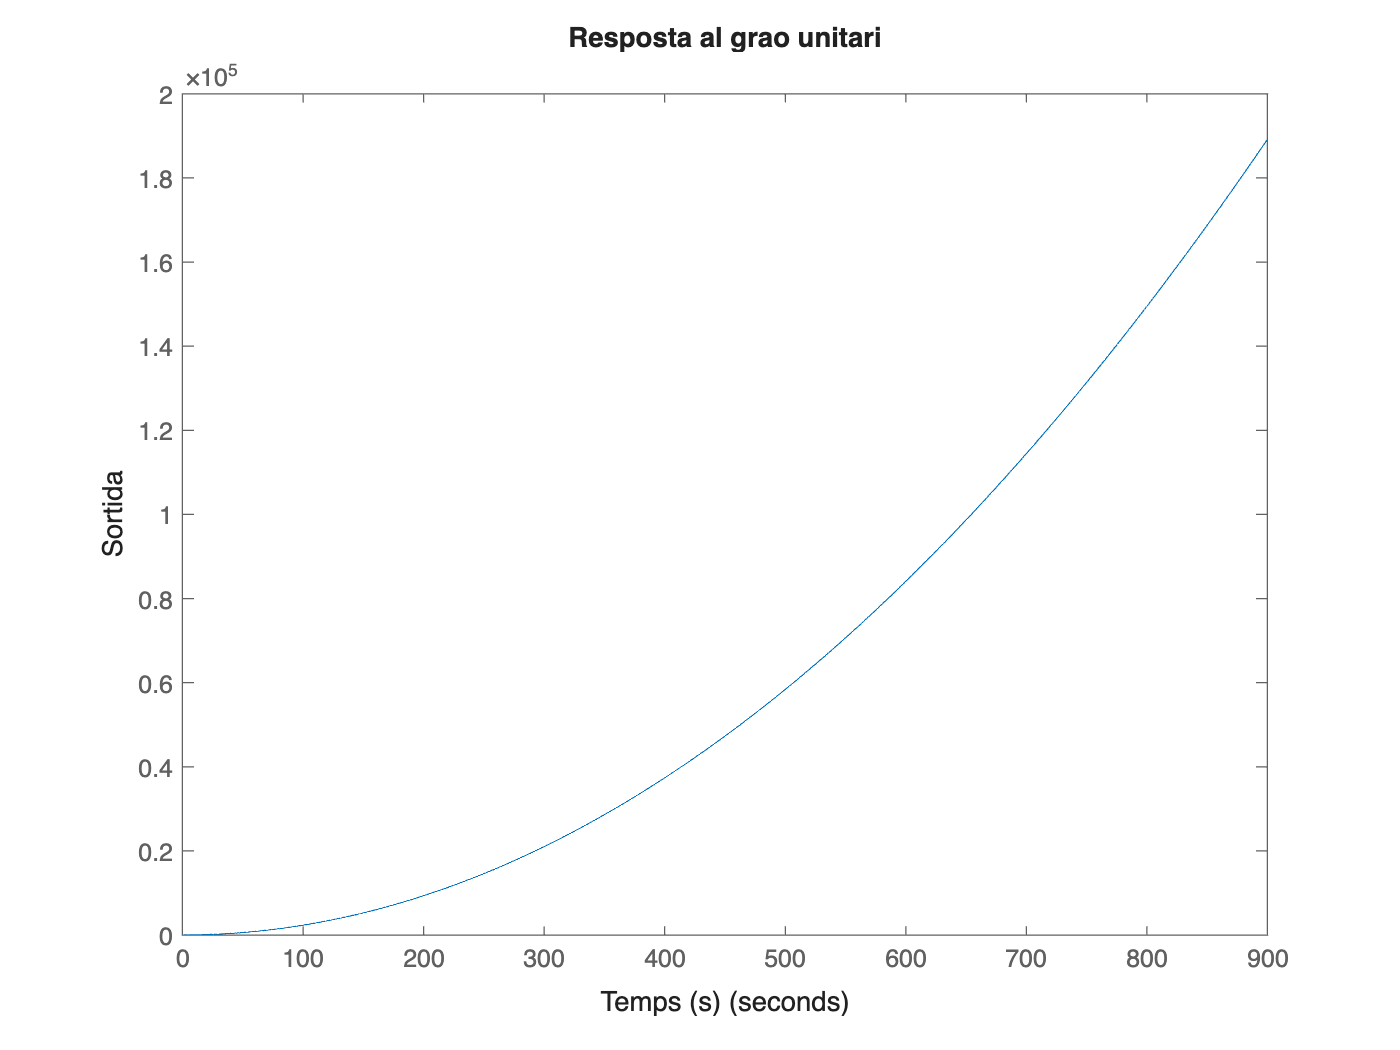


% 3. Respuesta al escalón unitario
figure;
step(G);
title('Resposta al grao unitari');
xlabel('Temps (s)');
ylabel('Sortida');

pidTuner(G, 'PID')

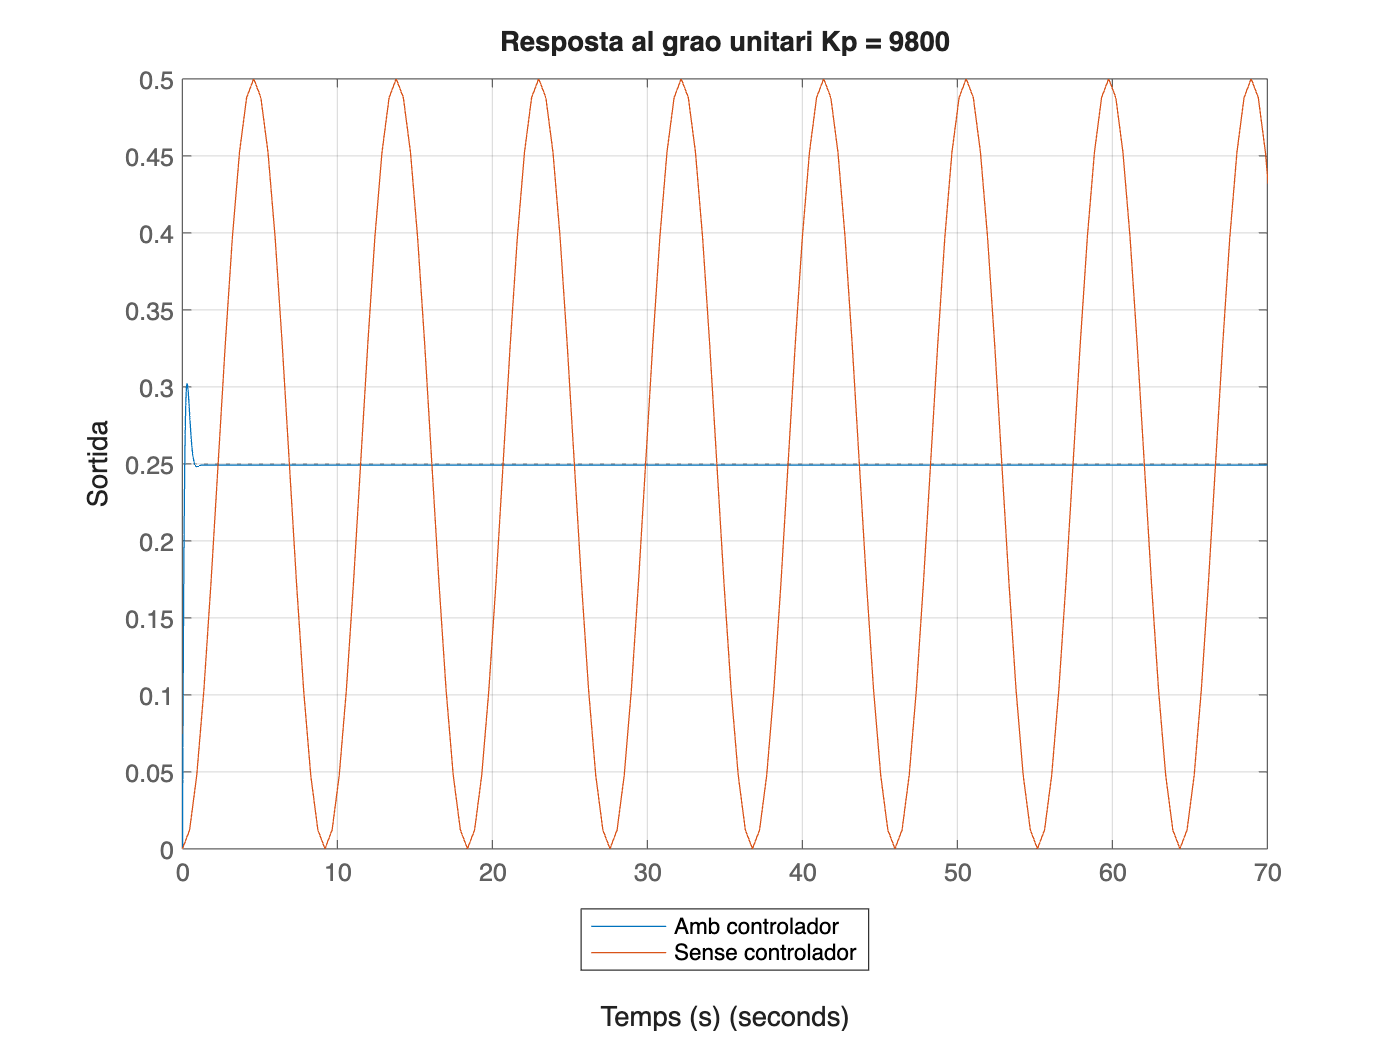

figure;
% Parámetros del controlador PID
Kp = 119; % Ganancia proporcional
Ki = 30.9; % Ganancia integral
Kd = 23.51; % Ganancia derivativa

% Definir el controlador PID
C = pid(Kp, Ki, Kd);

% Sistemas en lazo cerrado
sys_cl = feedback(C*G, 1); % Lazo cerrado con el controlador
sys = feedback(G, 1); % Lazo cerrado sin controlador

% Crear la figura y graficar las respuestas
figure;
step(1/4*sys_cl); % Respuesta del sistema con el controlador
hold on; % Superponer la siguiente gráfica
step(1/4*sys); % Respuesta del sistema sin el controlador

% Configurar los ejes
axis([0 70 0 0.5]);

% Configurar título y etiquetas
title('Resposta al grao unitari Kp = 9800');
xlabel('Temps (s)');
ylabel('Sortida');

% Añadir leyenda
legend('Amb controlador', 'Sense controlador', 'Location','southoutside');
grid on;
hold off

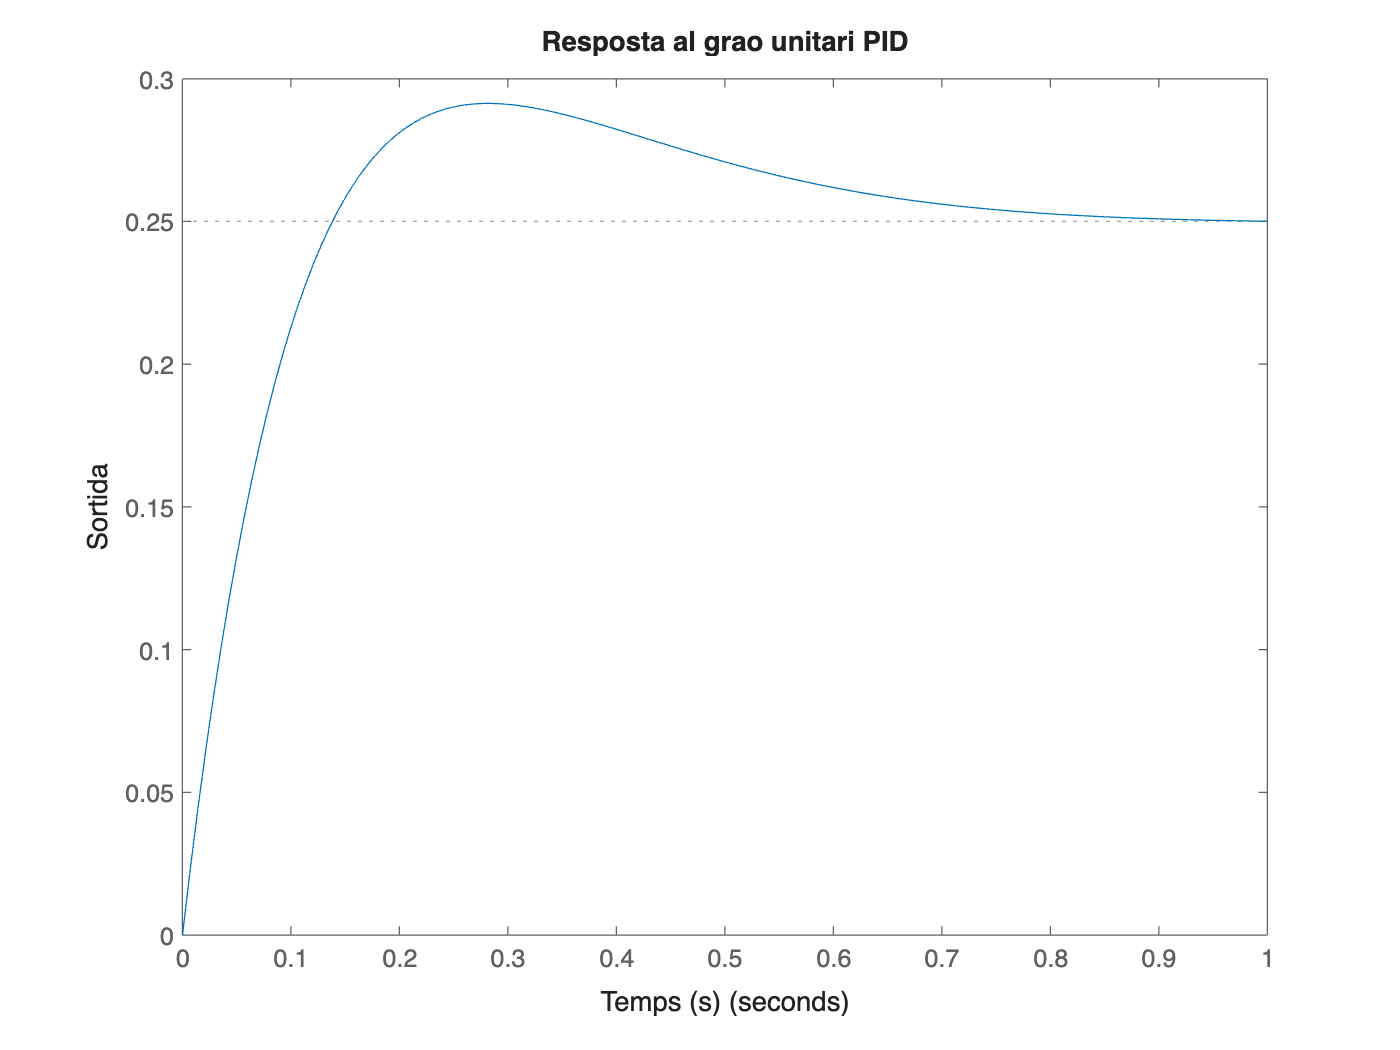

figure;
Kp = 119;
Ki = 35.9;
Kd = 28.51;

C = pid(Kp,Ki,Kd);

sys_cl=feedback(C*G,1);

t=0:0.01:10;
step(1/4*sys_cl)
title('Resposta al grao unitari PID');
xlabel('Temps (s)');
ylabel('Sortida');

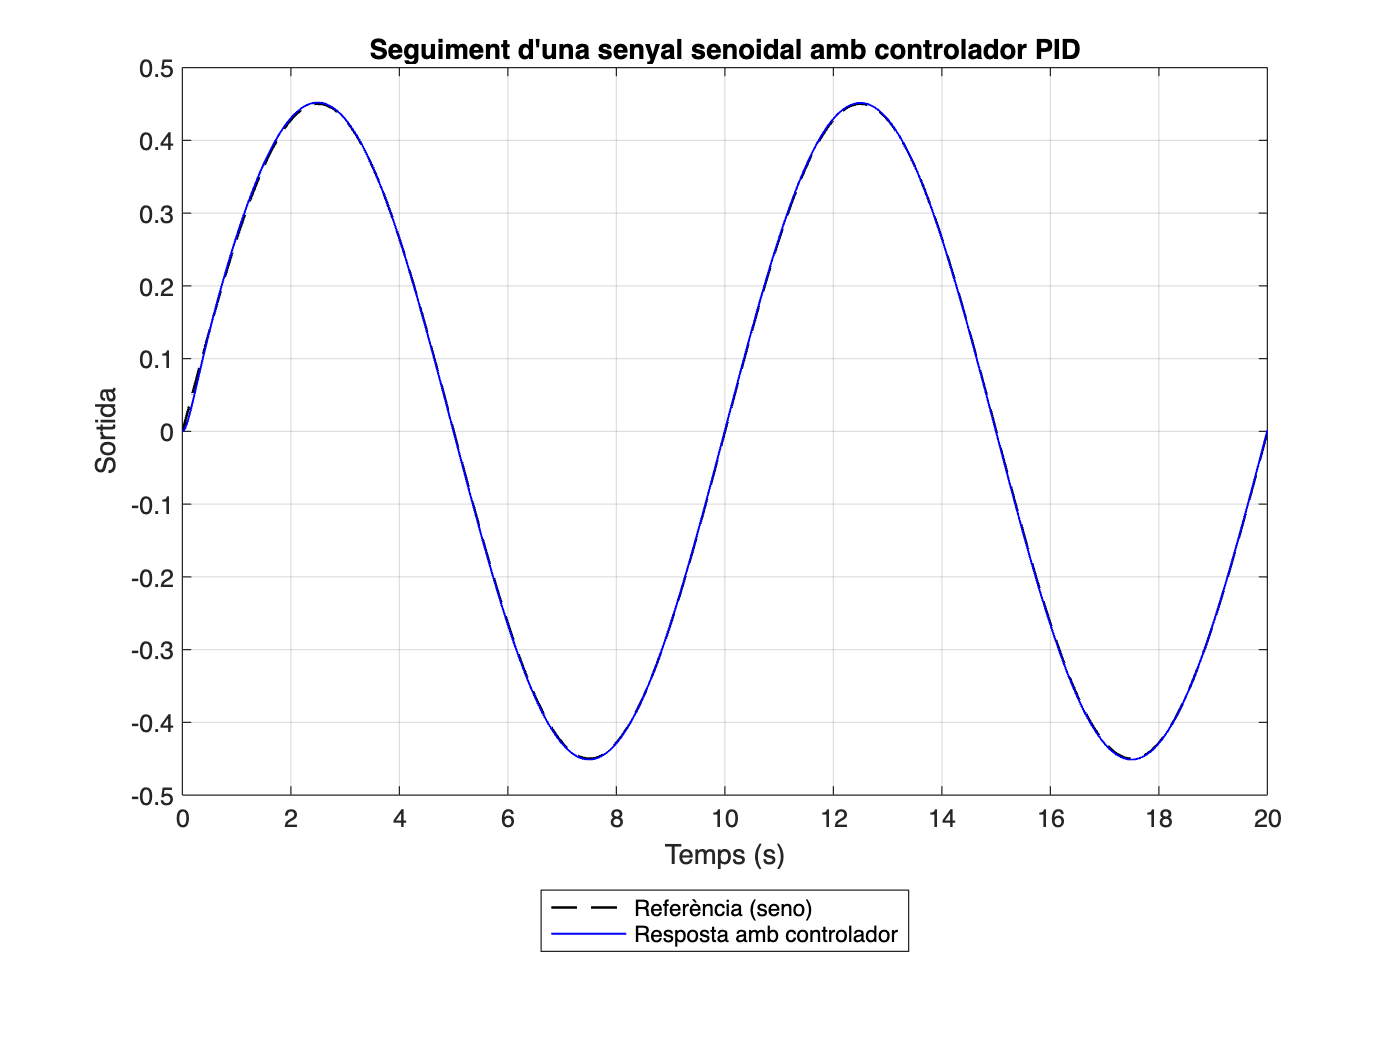

% Parámetros del controlador PID
Kp = 118.2592;
Ki = 106.4262;
Kd = 32.8519;
C = pid(Kp, Ki, Kd);

% Tiempo de simulación
t = 0:0.01:20;

% Entrada senoidal como referencia
omega = 2 * pi / 10;  % frecuencia (un ciclo cada 10 segundos)
r = 0.45 * sin(omega * t);

% Simulación de la respuesta con lsim (respuesta a entrada arbitraria)
sys_cl = feedback(C*G, 1);  % sistema en lazo cerrado con PID
y_pid = lsim(sys_cl, r, t);  % salida del sistema ante la referencia senoidal

% Graficar
figure;
plot(t, r, '--k', 'LineWidth', 1);  % Referencia
hold on;
plot(t, y_pid, 'b', 'LineWidth', 0.8);  % Respuesta con PID

% Opciones gráficas
title('Seguiment d''una senyal senoidal amb controlador PID');
xlabel('Temps (s)');
ylabel('Sortida');
legend('Referència (seno)', 'Resposta amb controlador', 'Location','southoutside');
grid on;
axis([0 20 -0.5 0.5]);
hold off;